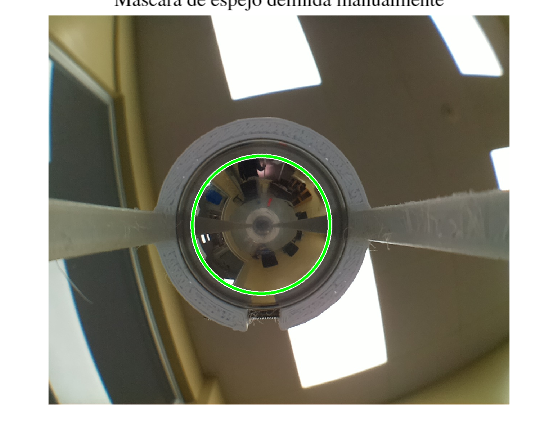

%% ------------------------------------------------------------
% Dibujo manual de la máscara del espejo
%% ------------------------------------------------------------

%% 1) Creación de la máscara sobre imagen de referencia
Iref = imread('C:\Users\GMADRO04\Documents\SOLER\QUPA\Testeo_QUPA\camara_QUPA\img_1280_curadas\img_20250726_064627.jpg');       % Imagen de referencia
figure; imshow(Iref);
title('Dibuja un circulo sobre el espejo y haz doble clic','Interpreter','latex');

% Dibuja y ajusta hasta cubrir el espejo
h = drawcircle('Color','r','LineWidth',2);
wait(h);  % espera al doble clic para finalizar

% Extrae centro y radio
pos = h.Center;   % [x y]
rad = h.Radius;   % radio en píxeles
delete(h);        % elimina el objeto interactivo
close;            % cierra la figura de referencia

% Construye máscara binaria circular
[H,W,~] = size(Iref);
[xg,yg] = meshgrid(1:W,1:H);
mask_ref = (xg - pos(1)).^2 + (yg - pos(2)).^2 <= rad.^2;

% Visualiza la máscara superpuesta para verificación
figure; imshow(Iref); hold on;
visboundaries(mask_ref,'Color','g','LineWidth',1.5);
title('Mascara de espejo definida manualmente','Interpreter','latex');

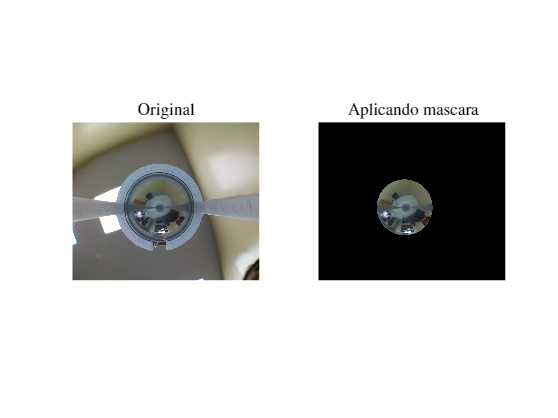

drawnow;

% Guarda la máscara y parámetros para reuso
save('C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\VisionsystemProject\calib_output\espejo_mask_1.mat','mask_ref','pos','rad');

% Ejemplo de aplicación a otra imagen
I = imread('C:\Users\GMADRO04\Documents\SOLER\QUPA\Testeo_QUPA\camara_QUPA\img_1280_curadas\img_20250726_053739.jpg');    % otra foto distinta
Iseg = I;
for c = 1:3
    tmp = I(:,:,c);
    tmp(~mask_ref) = 0;
    Iseg(:,:,c) = tmp;
end

figure(); 
subplot(1,2,1), imshow(I),   title('Original','Interpreter','latex');
subplot(1,2,2), imshow(Iseg), title('Aplicando mascara','Interpreter','latex');